# Center a molecule

Import a structure and center it

close all;
atom=import_atom('6x4MMT_x10y5z0.gro'); % A non-centered structure

Found .gro file
.gro file imported
Elapsed time is 0.263250 seconds.
Looking up bonds
Calculating the distance matrix


i =    960

Looking for neighbours/bonds
Composition info:


composition = struct with fields:
     resnames: {'MMT'}
    nresidues: 1
       natoms: 960

Atom_types = 1×4 cell array
    {'Al'}    {'H'}    {'O'}    {'Si'}

Atom_numbers =     96    96   576   192


The box dimensions are:


Box_dim =   31.187999999999999  36.060000000000002  10.000000000000000


atom=center_atom(atom,Box_dim); % This will also replicate Box_dim

Center to box
centering along x
centering along y
centering along z


ans =   -0.005000000000000

Scanning intramolecular bonds, neglecting the PBC
Calculating the distance matrix


i =    960

Looking for neighbours/bonds


Drawing the atoms


i =    960

Drawing the bonds


ans =         1000

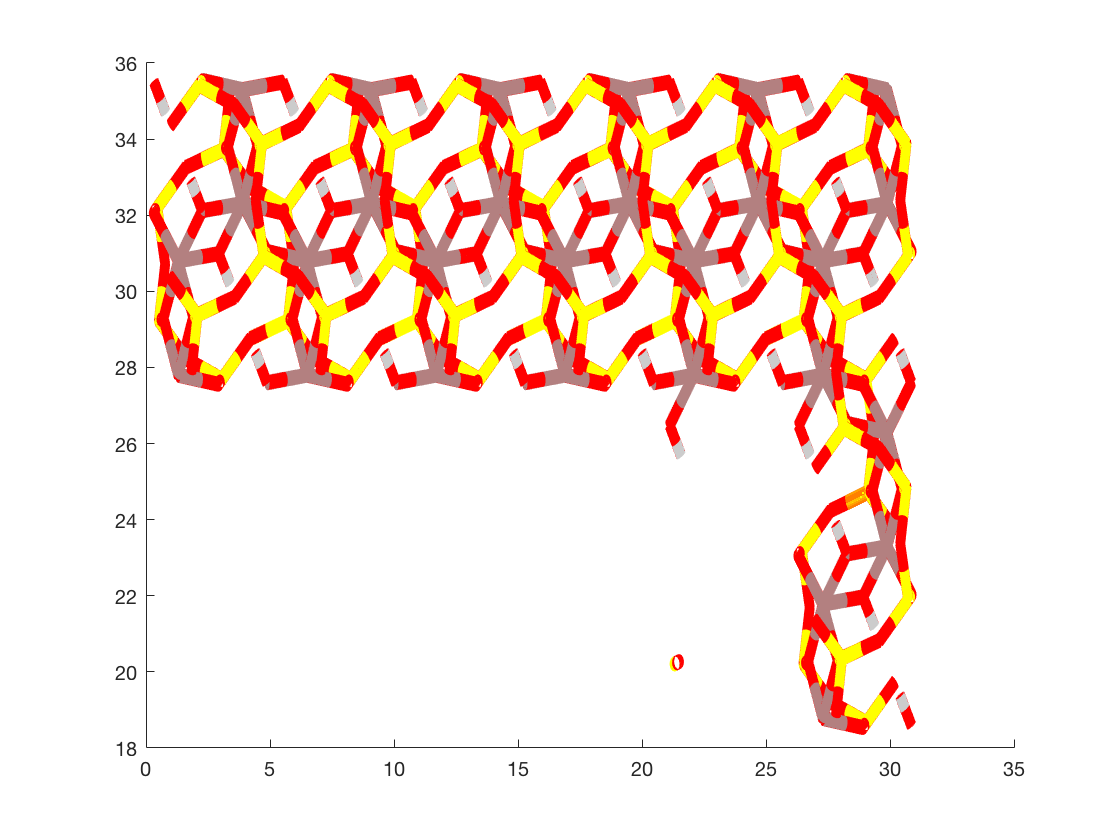

i =         1372

show_atom(atom,Box_dim,.1);

%vmd(atom,Box_dim)

We can also center with respect to a certain resname group (here `'MMT'`)

close all;
atom=import_atom('6x4MMT_x10y5z0.gro');
atom=center_atom(atom,Box_dim,'MMT'); % Default 'all'
show_atom(atom,Box_dim,.1);
%vmd(atom,Box_dim)

Or we can center with respect a certain x, y or z direction (here in the `'z'` direction)

close all;
atom=import_atom('6x4MMT_x10y5z0.gro');
atom=center_atom(atom,Box_dim,'MMT','z'); % Default 'xyz'
show_atom(atom,Box_dim,.1);
%vmd(atom,Box_dim)